data_filename = './sample_data/vectornav_pitch45_5_17.csv';

% Our sample data has headers on the first line, so skip it
data = csvread(data_filename, 1);

% We'll use the time that the sample starts as each time
time = data(:, 1) * 10^(-9);
time = time - time(1);

% Using the first timestamp, calculate the sampling rate.
% With the configuration for the VectorNav, this will remain consistent.
sampling_rate = 1 / (time(2) - time(1));

yaw_pitch_roll_device = data(:, 4:6);
% IMU initialized using magnetometer.  Remove this bias.
%yaw_pitch_roll_device(:, 1) = yaw_pitch_roll_device(:, 1) - yaw_pitch_roll_device(1, 1);
orientation_device = quaternion(angle2quat(yaw_pitch_roll_device(:, 1), yaw_pitch_roll_device(:, 2), yaw_pitch_roll_device(:, 3)));
accel = data(:, 10:12);
gyro = data(:, 7:9);
mag = data(:, 19:21);

ahrs_sensor_data = table;
ahrs_sensor_data.Accelerometer = accel;
ahrs_sensor_data.Gyroscope = gyro;
ahrs_sensor_data.Magnetometer = mag;

imu_sensor_data = table;
imu_sensor_data.Accelerometer = accel;
imu_sensor_data.Gyroscope = gyro;

ground_truth = table;
ground_truth.Orientation = orientation_device;

ahrs_fuse = ahrsfilter('SampleRate', sampling_rate, 'ReferenceFrame', 'ENU');
imu_fuse = imufilter('SampleRate', sampling_rate, 'ReferenceFrame', 'ENU');

orientation_ahrs_untuned = ahrs_fuse(accel, gyro, mag);
orientation_imu_untuned = imu_fuse(accel, gyro);
yaw_pitch_roll_ahrs_untuned = eulerd(orientation_ahrs_untuned,'ZYX','frame');
yaw_pitch_roll_imu_untuned = eulerd(orientation_imu_untuned,'ZYX','frame');

ahrs_cfg = tunerconfig('ahrsfilter');
imu_cfg = tunerconfig('imufilter');
tune(ahrs_fuse, ahrs_sensor_data, ground_truth, ahrs_cfg);

    Iteration    Parameter                         Metric
    _________    _________                         ______
    1            AccelerometerNoise                2.9254
    1            GyroscopeNoise                    2.9254
    1            MagnetometerNoise                 2.9254
    1            GyroscopeDriftNoise               2.9254
    1            LinearAccelerationNoise           2.9253
    1            MagneticDisturbanceNoise          2.9253
    1            LinearAccelerationDecayFactor     2.9253
    1            MagneticDisturbanceDecayFactor    2.9253
    2            AccelerometerNoise                2.9253
    2            GyroscopeNoise                    2.9253
    2            MagnetometerNoise                 2.9253
    2            GyroscopeDriftNoise               2.9253
    2            LinearAccelerationNoise           2.9253
    2            MagneticDisturbanceNoise          2.9253
    2            LinearAccelerationDec

tune(imu_fuse, imu_sensor_data, ground_truth, imu_cfg);

    Iteration    Parameter                        Metric
    _________    _________                        ______
    1            AccelerometerNoise               2.7402
    1            GyroscopeNoise                   2.7402
    1            GyroscopeDriftNoise              2.7402
    1            LinearAccelerationNoise          2.7402
    1            LinearAccelerationDecayFactor    2.7402
    2            AccelerometerNoise               2.7402
    2            GyroscopeNoise                   2.7402
    2            GyroscopeDriftNoise              2.7402
    2            LinearAccelerationNoise          2.7402
    2            LinearAccelerationDecayFactor    2.7402
    3            AccelerometerNoise               2.7402
    3            GyroscopeNoise                   2.7402
    3            GyroscopeDriftNoise              2.7402
    3            LinearAccelerationNoise          2.7402
    3            LinearAccelerationDecayFactor    2.74

orientation_ahrs_tuned = ahrs_fuse(accel, gyro, mag);
orientation_imu_tuned = imu_fuse(accel, gyro);
yaw_pitch_roll_ahrs_tuned = eulerd(orientation_ahrs_tuned,'ZYX','frame');
yaw_pitch_roll_imu_tuned = eulerd(orientation_imu_tuned,'ZYX','frame');

% AHRS takes magnetometer into account. So that we can compare, remove this bias.
%yaw_pitch_roll_ahrs(:, 1) = yaw_pitch_roll_ahrs(:, 1) - yaw_pitch_roll_ahrs(1, 1);

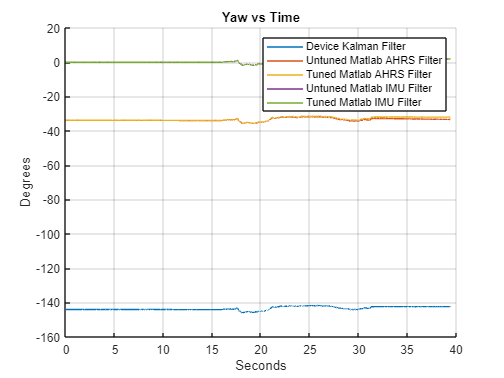

clf;
hold on;
plot(time, yaw_pitch_roll_device(:, 1));
plot(time, yaw_pitch_roll_ahrs_untuned(:, 1));
plot(time, yaw_pitch_roll_ahrs_tuned(:, 1));
plot(time, yaw_pitch_roll_imu_untuned(:, 1));
plot(time, yaw_pitch_roll_imu_tuned(:, 1));
ylabel("Degrees");
xlabel("Seconds")
title("Yaw vs Time");
legend("Device Kalman Filter", "Untuned Matlab AHRS Filter", "Tuned Matlab AHRS Filter", "Untuned Matlab IMU Filter", "Tuned Matlab IMU Filter");
grid on;
hold off;

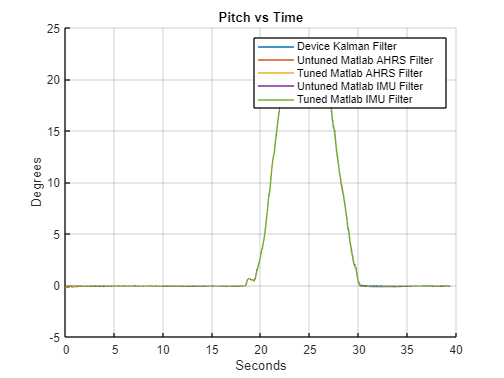

clf;
hold on;
plot(time, yaw_pitch_roll_device(:, 2));
plot(time, yaw_pitch_roll_ahrs_untuned(:, 2));
plot(time, yaw_pitch_roll_ahrs_tuned(:, 2));
plot(time, yaw_pitch_roll_imu_untuned(:, 2));
plot(time, yaw_pitch_roll_imu_tuned(:, 2));
ylabel("Degrees");
xlabel("Seconds")
title("Pitch vs Time");
legend("Device Kalman Filter", "Untuned Matlab AHRS Filter", "Tuned Matlab AHRS Filter", "Untuned Matlab IMU Filter", "Tuned Matlab IMU Filter");
grid on;
hold off;

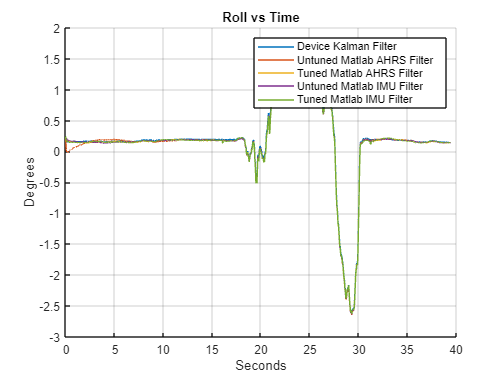

clf;
hold on;
plot(time, yaw_pitch_roll_device(:, 3));
plot(time, yaw_pitch_roll_ahrs_untuned(:, 3));
plot(time, yaw_pitch_roll_ahrs_tuned(:, 3));
plot(time, yaw_pitch_roll_imu_untuned(:, 3));
plot(time, yaw_pitch_roll_imu_tuned(:, 3));
ylabel("Degrees");
xlabel("Seconds")
title("Roll vs Time");
legend("Device Kalman Filter", "Untuned Matlab AHRS Filter", "Tuned Matlab AHRS Filter", "Untuned Matlab IMU Filter", "Tuned Matlab IMU Filter");
grid on;
hold off;